# Script for sequencing

## Update cycle number and cycle type

%user inputs
datafolder="20210101_test";
%maxproj_login="imagestorage@10.128.26.83";
%maxproj_folder="/mnt/imagestorage/";
maxproj_login="imagestorage@10.128.26.83";
maxproj_folder="/mnt/imagestorage/";
cycletype="geneseq"; %geneseq, hyb, or bcseq
cyclenum= 1;
person="AZ";


clc
cycletype=char(cycletype);
maxproj_login=char(maxproj_login);
maxproj_folder=char(maxproj_folder);
datafolder=char(datafolder);
person=char(person);

datafolderfull=['e:/',datafolder];
if ~exist(datafolderfull,'dir')
    mkdir(datafolderfull)
    fprintf('Data folder created.')
else
    cd(datafolderfull)
    fprintf('Data folder exists. Changed pwd to data folder.')
end 

Error using mkdir
The system cannot find the path specified.



%generate file names and paths
cycle_name=[cycletype,num2str(cyclenum,'%.2u')];
focus_folder=['focus',cycle_name];
switch cycletype
    case 'geneseq'
        focusch=1;
        if cyclenum==1
            
            %ch_seq=[2 1 3 4 5]; tformch=[2 4];%original fast-seq
            %ch_seq=[2 1 3 4 5 6 7] tformch=[2 4 6]; %fastseq with additiona C
            ch_seq=[2 1 3 4 5]; tformch=[]; %single-seq
        else
            %ch_seq=[2 1 3 4]; tformch=[2 4];
            %ch_seq=[2 1 3 4 5 6];  tformch=[2 4 6];
            ch_seq=[2 1 3 4]; tformch=[]; %single-seq
        end
    case 'bcseq'
        focusch=1;
        if cyclenum==1
            %ch_seq=[2 1 3 4 5]; tformch=[2 4];%original fast-seq
            %ch_seq=[2 1 3 4 5 6 7] tformch=[2 4 6]; %fastseq with additiona C
            ch_seq=[2 1 3 4 5]; tformch=[]; %single-seq
        else
            %ch_seq=[2 1 3 4]; tformch=[2 4];
            %ch_seq=[2 1 3 4 5 6];  tformch=[2 4 6];
            ch_seq=[2 1 3 4]; tformch=[]; %single-seq
        end
    case 'hyb'
        focusch=1;
        %ch_seq=[2 6 1 5 4 3]; tformch=[2 4 6]; % need to double check this
        ch_seq=[1 5 2 6 3 4]; tformch=[]; %hyb using C1
end

switch person
    case 'XC'
        phone_num='3472297764';
        serviceprovider='tmobile';
    case 'AZ'
        phone_num='8062524188';
        serviceprovider='att';
end

fprintf('Please confirm Data folder: %s\n',datafolderfull);
fprintf('Please confirm cycle name: %s\n',[cycletype,num2str(cyclenum,'%.2u')]);
fprintf('Please confirm %s is running the experiment. \n',person);

- **Load offsetgeneseq01.csv in Elements, resave the list with the current cycle number/name.**

- **Use DIC live channel to check for xy positions to make sure slides are mounted correctly.**

- **Collect focus stacks.**

## Run focus after collecting the focusing stack and save the position list.

 
%offset=rand(1,8)*30;
fprintf('Calculating focus for %s ...',[cycle_name,'.csv']);

Calculating focus for hyb01.csv ...

offset=niefindfluorfocusfast_concurrent([cycle_name,'.csv'],focus_folder,-30,30,1.5,focusch);    
%openvar offset
fprintf('Done! Focused positions saved to %s\n',['offset',cycle_name,'.csv']);

Done! Focused positions saved to offsethyb01.csv


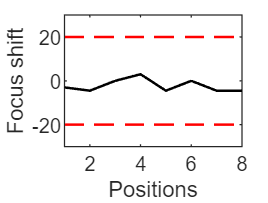

figure;plot(offset,'-k','LineWidth',1);
hold on;
plot([1 numel(offset)],[20 20],'--r','LineWidth',1);
plot([1 numel(offset)],[-20 -20],'--r','LineWidth',1);
set(gca,'ylim',[-30 30],'xlim',[1 numel(offset)]);
xlabel('Positions')
ylabel('Focus shift');

I=abs(offset)>20;
if sum(I)>0
    fprintf('Please check the following positions with extreme shifts: \n');
    idx=find(I);
    fprintf('Position %u: Shift %u\n',[idx,round(offset(idx))]')
else
    fprintf('All points appear to focus fine.');
end

All points appear to focus fine.

**        If needed, manually adjust offset position list and resave it in Elements.**

## Create tiles after confirmed offset position list. 

 
niecreatetilesuneven(['offset',cycle_name,'.csv'],3200,0.32,20);
fprintf('Tiled position list saved to %s\n',['tiledoffset',cycle_name,'.csv']);

Tiled position list saved to tiledoffsethyb01.csv


fprintf('Position information saved to %s\n',['Posinfo_offset',cycle_name,'.mat']);

Position information saved to Posinfo_offsethyb01.mat


- **Load the correct imaging profile in Elements**

- **Load the tiled position list**

- **Start acquisition in Elements**

## After starting acquisition in Elements, run this during imaging

 
load tformhyb
load tformseq
load tformsingle
switch cycletype
    case 'geneseq'
        %tform=tformseq;
        tform=tformsingle;
    case 'bcseq'
        %tform=tformseq;
        tform=tformsingle;
    case 'hyb'
        %tform=tformhyb;
        tform=tformsingle;
end
fprintf('Starting max projection on cycle %s and transfer to storage server...', [cycletype,num2str(cyclenum,'%.2u')]);

Starting max projection on cycle hyb01 and transfer to storage server...

 niemaxprojimaging(cycle_name,ch_seq,tformch,30,['Posinfo_offset',cycle_name,'.mat'], ...
     tform,maxproj_login, ...
     [maxproj_folder,datafolder],['d:\',datafolder]);

Created local designated maxproj folder.
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
Created remote folder.
Waiting 30 sec.
Waiting 7.249051e+00 sec.
Waiting 8.985907e+00 sec.
Waiting 8.951742e+00 sec.
Waiting 9.093157e+00 sec.
Waiting 8.399445e+00 sec.
Waiting 7.349553e+00 sec.
Waiting 9.062161e+00 sec.
Waiting 8.114738e+00 sec.
Waiting 8.209492e+00 sec.
Waiting 9.133986e+00 sec.
Waiting 8.480268e+00 sec.
Waiting 8.683798e+00 sec.
Waiting 9.504006e+00 sec.
Waiting 8.706699e+00 sec.
Waiting 8.667370e+00 sec.
Waiting 8.147162e+00 sec.
Waiting 9.313202e+00 sec.
Waiting 8.455644e+00 sec.
Waiting 8.359749e+00 sec.
Waiting 9.152441e+00 sec.
Waiting 8.211494e+00 sec.
Waiting 8.356799e+00 sec.
Waiting 8.312902e+00 sec.
Waiting 8.960735e+00 sec.
Waiting 8.229993e+00 sec.
Waiting 8.385013e+00 sec.
Waiting 8.987876e+00 sec.
Waiting 7.912554e+00 sec.
Waiting 8.072374e+00 sec.
Waiting 8.217538e+00 sec.
Waiting 8.870538e+00 s

fprintf('Max projection complete, checking if transfer is complete ...')

Max projection complete, checking if transfer is complete ...

[status,cmdout]=system(['ssh     ',maxproj_login, ...
    ' "ls ',maxproj_folder,datafolder,'/',cycle_name, ...
    '/*.tif | wc -l" ']);
localfiles=dir(['d:\',datafolder,'\',cycle_name,'\*.tif']);
if numel(localfiles)==str2double(cmdout)
    fprintf('Remote and local file numbers match. Transfers complete! \n');
    send_text_message(phone_num,serviceprovider,'Seq status:','Cycle finished');
else
    send_text_message(phone_num,serviceprovider,'Seq error:','File numbers do not match');
    error('Error: Remote and local file numbers do not match, please manually check files!');
    
end

Remote and local file numbers match. Transfers complete! 
